% Data (from your table)
f_MHz = [1 5 10 15 20 25 30 35 40 45 50];
Vi_mV = [105 107 107 107 107 110 114 115 113 109 102];
VL_mV = [118 119 119 118 118 118 119 118 118 115 116];
phi_deg_meas = [4 18 40 58 76 98 112 132 150 167 180];

% Theory parameters
ell = 2.06;                 % m (DUT only)
VF  = 0.66;                 % RG58
up  = VF*3e8;               % m/s
tau = ell/up;               % s ~ 10 ns
f = linspace(1,50,400);     % MHz for smooth theory lines

% Theory curves
Vi_th = 100*ones(size(f));  % mV (ideal 50-50 divider with Vg=200 mV)
VL_th = Vi_th;              % lossless matched line
phi_deg_th = -360 .* (f*1e6) .* tau;  % deg

% Fit measured phase to get delay & VF from your data
p = polyfit(f_MHz, phi_deg_meas, 1);     % phi ≈ p(1)*f + p(2)
slope_deg_per_MHz = p(1);
tau_fit = slope_deg_per_MHz/(360e6);     % s
up_fit  = ell/tau_fit;                   % m/s
VF_fit  = up_fit/3e8;

fprintf('Fit: slope=%.3f deg/MHz, tau=%.2f ns, up=%.2e m/s, VF=%.3f\n', ...
        slope_deg_per_MHz, 1e9*tau_fit, up_fit, VF_fit);

Fit: slope=3.651 deg/MHz, tau=10.14 ns, up=2.03e+08 m/s, VF=0.677


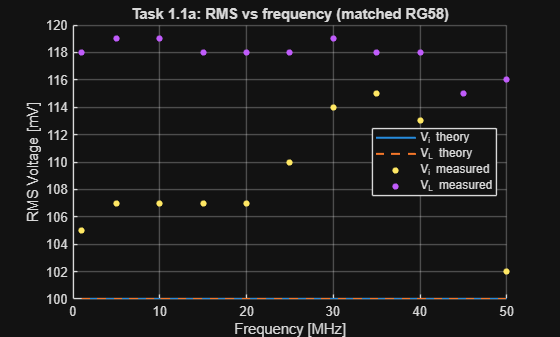



figure; hold on; grid on;
plot(f, Vi_th, 'LineWidth',1.5);
plot(f, VL_th, '--', 'LineWidth',1.5);
plot(f_MHz, Vi_mV, '.', 'MarkerSize',14);
plot(f_MHz, VL_mV, '.', 'MarkerSize',14);
xlabel('Frequency [MHz]'); ylabel('RMS Voltage [mV]');
legend('V_i theory','V_L theory','V_i measured','V_L measured','Location','best');
title('Task 1.1a: RMS vs frequency (matched RG58)');

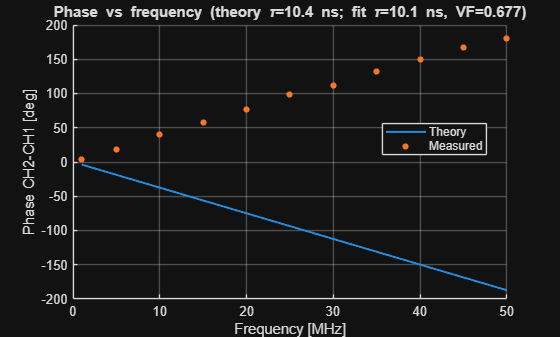


figure; hold on; grid on;
plot(f, phi_deg_th, 'LineWidth',1.5);
plot(f_MHz, phi_deg_meas, '.', 'MarkerSize',14);
xlabel('Frequency [MHz]'); ylabel('Phase CH2-CH1 [deg]');
title(sprintf('Phase vs frequency (theory \\tau=%.1f ns; fit \\tau=%.1f ns, VF=%.3f)', ...
              1e9*tau, 1e9*tau_fit, VF_fit));
legend('Theory','Measured','Location','best');

Z0  = 50;
ell = 2.01;          % m (your measured cable+connectors)
up  = 0.66*3e8;      % m/s (or compute from your measured Δf)
% ---- Measured extrema (edit these) ----
Vi_max_mV = 139;           % e.g., [132 129 131]
f_max_MHz = 48;           % their frequencies
Vi_min_mV = 80;           % e.g., [88 90 89]
f_min_MHz = 24;           % their frequencies

% --- VSWR & |Gamma| ---
S = Vi_max_mV / Vi_min_mV;  
rho = (S-1)/(S+1);             % |Gamma_L|

% --- Angle of Gamma from one (or average of many) maxima ---
fm = mean(f_max_MHz)*1e6;      % Hz
ang = mod(4*pi*ell*fm/up, 2*pi);  % radians, using a MAX
% If you used a MIN instead, do: ang = mod(4*pi*ell*fm/up + pi, 2*pi);

GammaL = rho * exp(1j*ang);    % complex reflection coefficient
ZL = Z0 * (1 + GammaL) / (1 - GammaL);

fprintf('VSWR S=%.3f, |Gamma|=%.3f, angle=%.1f deg\n', S, rho, rad2deg(ang));

VSWR S=1.738, |Gamma|=0.269, angle=350.8 deg


fprintf('Estimated load: ZL = %.2f %+.2fj ohms\n', real(ZL), imag(ZL));

Estimated load: ZL = 85.77 -7.94j ohms
